%CTSDM PARAMETER


%ntf
N=3;
osr=500/3;
OBG=1.5;

ntf = synthesizeNTF(3,500/3,1,1.5,0)

ntf =
 
         (z-1) (z^2 - 2z + 1)
  ----------------------------------
  (z-0.6694) (z^2 - 1.531z + 0.6639)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



% 
% % [a,g,b,c] = realizeNTF(H,'CIFF');
% % ABCD = stuffABCD(a,g,b,c,'CIFF');
% % [ABCDs,umax]=scaleABCD(ABCD,2,0,1,7,1e5,10);
% % [ntf,stf] = calculateTF(ABCDs);
% 
% Hz = 1/ntf-1
% Hs = d2c(Hz)
% 
% k1=0.67033;
% k2=0.24413;
% k3 = 0.04398;
% c1=1;
% c2=1;
% c3=1;


ABCDc = realizeNTF_ct(ntf,'FF',[0/20 20/20])%no delay

ABCDc =          0         0         0    1.0000   -1.0000
    1.0000         0   -0.0002         0         0
         0    1.0000         0         0         0
    0.6703    0.2440    0.0439         0   -0.0000


% [ntf,stf] = calculateTF(ABCDc,1)

[ABCDs,umax] = scaleABCD(ABCDc,2,0,0.5,7,0.78,1e5,10)

Please compile the mex version with "mex simulateDSM.c"
Please compile the mex version with "mex simulateDSM.c"
Please compile the mex version with "mex simulateDSM.c"
Please compile the mex version with "mex simulateDSM.c"
Please compile the mex version with "mex simulateDSM.c"
Please compile the mex version with "mex simulateDSM.c"
Please compile the mex version with "mex simulateDSM.c"
Please compile the mex version with "mex simulateDSM.c"
Ple

ABCDs =          0         0         0    0.2758   -0.2758
    1.0000         0   -0.0002         0         0
         0    1.0000         0         0         0
    2.4306    0.8848    0.1590         0   -0.0000


umax = 0.7800

%积分器输出摆幅0.5，量化器输入摆幅7，最大输入摆幅0.78

[a,g,b,c] = mapABCD(ABCDs,'CIFF')

a =     2.4306    0.8848    0.1590


g = 2.1318e-04

b =     0.2758         0         0         0


c =     0.2758    1.0000    1.0000


ABCDf=stuffABCD(a,g,b,c,'CIFF')

ABCDf =     1.0000         0         0    0.2758   -0.2758
    1.0000    1.0000   -0.0002         0         0
         0    1.0000    1.0000         0         0
    2.4306    0.8848    0.1590         0         0


[ntf,stf] = calculateTF(ABCDf,1)

ntf =
 
         (z-1) (z^2 - 2z + 1)
  ----------------------------------
  (z-0.6664) (z^2 - 1.663z + 0.7952)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.


stf =
 
   0.67032 (z^2 - 1.636z + 0.7016)
  ----------------------------------
  (z-0.6664) (z^2 - 1.663z + 0.7952)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



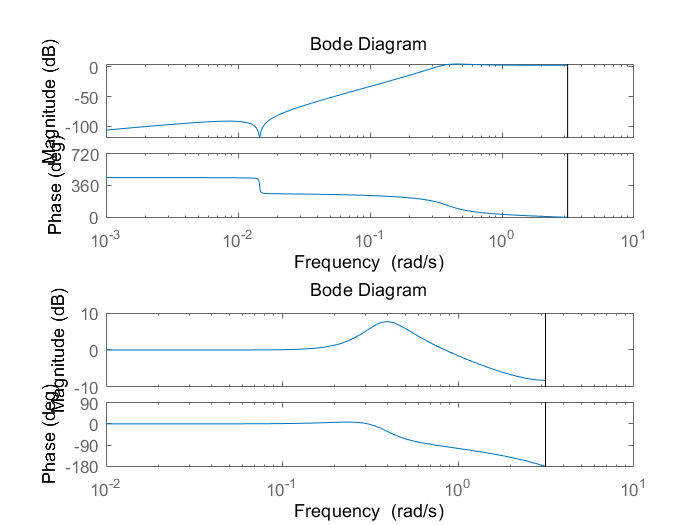

subplot(2,1,1);
bode(ntf);
subplot(2,1,2);
bode(stf);


Hz = 1/ntf - 1

Hz =
 
  0.67032 (z^2 - 1.636z + 0.7016)
  -------------------------------
       (z-1) (z^2 - 2z + 1)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



Hc=d2c(Hz)

Hc =
 
  0.56295 (s^2 + 0.3552s + 0.07815)
  ---------------------------------
  s (s^2 - 0.0002132s + 0.0002132)
 
Continuous-time zero/pole/gain model.




k1=
k2=
k3=





%CTSDM PARAMETER
fs = 8e+06;
Ts = 1/fs;

fin = 24e+03;
Tin = 1/fin;

peroid =100;%total simulation periods

time = peroid*Tin;% total simulation time
t = 0:Ts:time; %simulation t
n =length(t);






